**Convolución de señales**

La convolución es una operación que se realiza entre dos señales.

Variables de tiempo

N=10;
n=0:N;

Generación de dos funciones reales a partir de exponenciales complejas

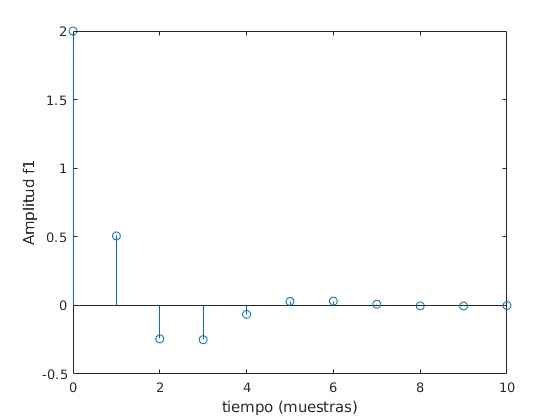

% parámetros función 1 (polares)
r1=0.5;
p1=1.04;
% parámetros función 2 (cartesianos)
re2=-0.4;
im2=0.5;

%Gráfica funcion 1 
f1=r1.^n.*(cos(p1*n)+1i*sin(p1*n)) + r1.^n.*(cos(p1*n)-1i*sin(p1*n));
figure
stem(n,f1)
xlabel('tiempo (muestras)')
ylabel('Amplitud f1')

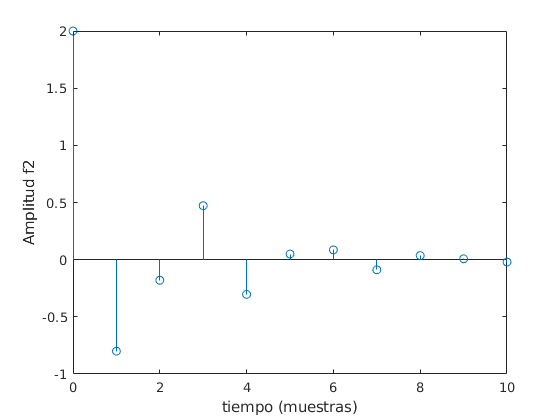


%Gráfica funcion 2
f2=(re2+1i*im2).^n + (re2-1i*im2).^n;
figure
stem(n,f2)
xlabel('tiempo (muestras)')
ylabel('Amplitud f2')

Convolución de las dos señales

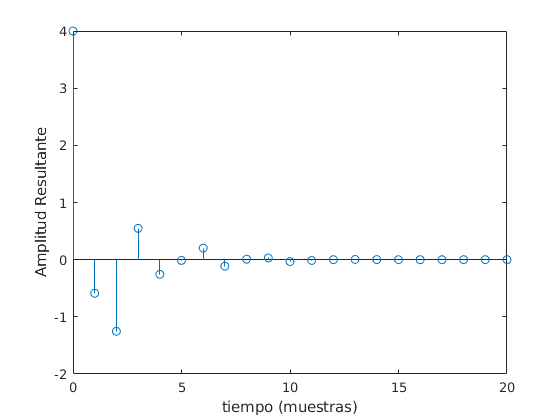

% constantes
A1=0.8;
A2=0.1;
% convolución
Ff=conv(f1,f2);
Nf=length(Ff);
nf=0:Nf-1;
figure
stem(nf,Ff)
xlabel('tiempo (muestras)')
ylabel('Amplitud Resultante')

Propiedad conmutativa de la convolución

Note como los resultados son iguales (salvo errores aproximación).

Fg=conv(f2,f1);
stem(nf,Ff)
xlabel('tiempo (muestras)')
ylabel('Amplitud Resultante')

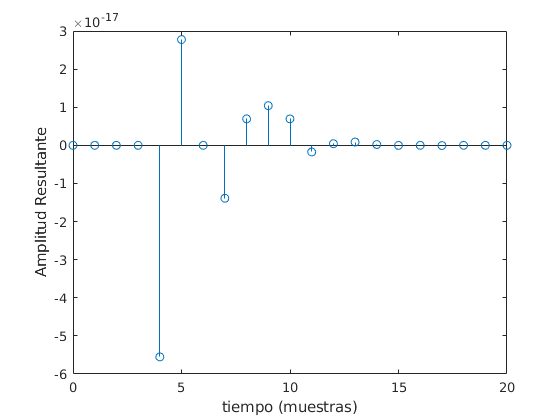

% diferencia entre Ff y Fg
df=Ff-Fg;
stem(nf,df)
xlabel('tiempo (muestras)')
ylabel('Amplitud Resultante')